# Trabajo práctico: Filtrado digital FIR

## 4) Filtrado por ventanas en MATLAB

### a) Use la herramienta filterDesigner para diseñar un filtro pasa-banda con frecuencias de corte de 300 Hz y 3400 Hz (canal telefónico), con ventana Kaiser con $\beta = 7.5$, orden 10, con formato punto flotante, precisión doble.

Fs = 44100; N = 10;
filt = filter_kaiser(N, Fs); % Modificado para recibir el orden y frecuencia de sampleo
disp(filt);

     FilterStructure: 'Direct-Form FIR'
          Arithmetic: 'double'         
           Numerator: [1x11 double]    
    PersistentMemory: false            
                                       


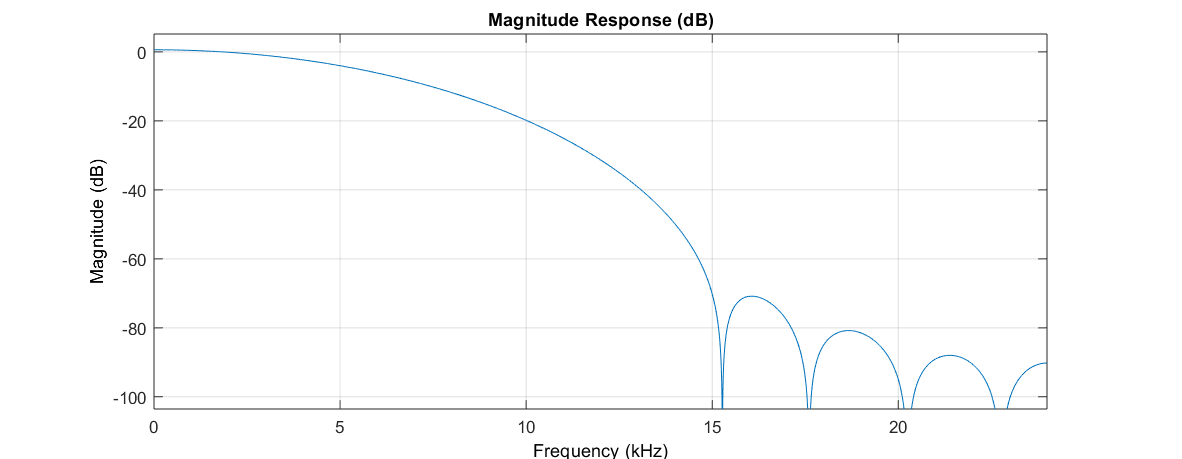

### b) Aumente el orden del filtro a 50. ¿Se modifica la respuesta en frecuencia del filtro?.

filt = filter_kaiser(50, Fs);

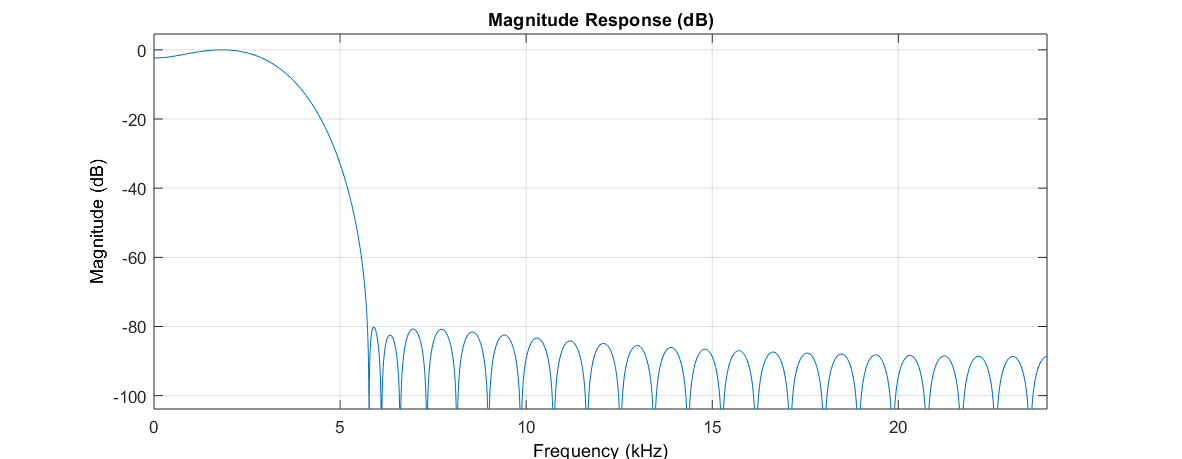

Se puede observar cómo la respuesta en frecuencia del filtro mejora al incrementar el orden. 

### c) Utilice como señal de entrada el archivo Tchaikovsky.mat.

load("Tchaikovsky.mat");

### d) Aplique a la señal de interés el filtro diseñado en el punto b).

signal_f = filter(filt, signal(:, 1));
sound(signal_f, 48e3);

### e) Grafique los espectros de la señal original y filtrada.

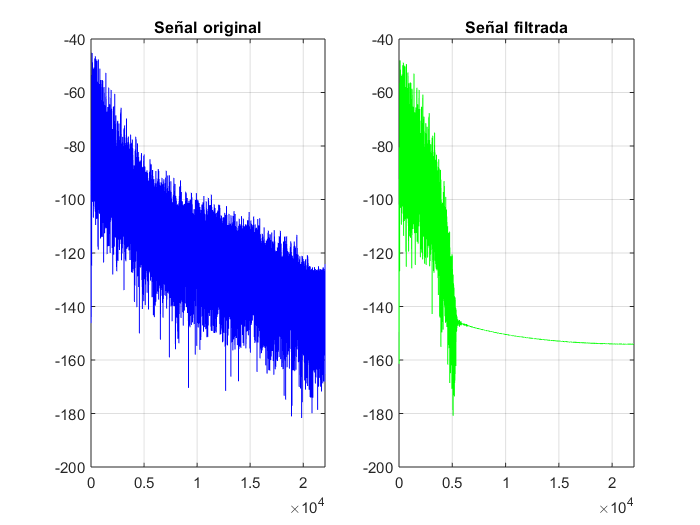

data = [signal(:, 1)'; signal_f'];
[f, dft_mag, dft_phase, dft, NFFT] = my_dft(data, Fs);

figure(1)
subplot(1, 2, 1);
plot(f, mag2db(dft_mag(:, 1)), '-b');
grid on;
title("Señal original");

subplot(1, 2, 2);
plot(f, mag2db(dft_mag(:, 2)), '-g');
grid on;
title("Señal filtrada");

### f) Examine ambas gráficas. ¿Qué diferencia observa entre ambas señales?

Se puede observar que en la señal filtrada hay atenuación de frecuencias a partir de la frecuencia de corte, y a partir de los 5 kHz la magnitud de las frecuencias es prácticamente nula.